% matlab programming

% 1.1 analysis of char. curve

% (a) roots, min/max, point of inflection


% f(x) = 4x^4 − 2x^3 − 18x^2 + 8x + 8

syms x

% equation

f = 4*x^4 - 2*x^3 - 18*x^2 + 8*x + 8

$$f = 4\,x^{4}-2\,x^{3}-18\,x^{2}+8\,x+8$$


% first derevative of 'f'

f_d = diff(f,x)

$$f\_d = 16\,x^{3}-6\,x^{2}-36\,x+8$$


% second derivative of 'f'

f_dd = diff(f,x,2)

$$f\_dd = 48\,x^{2}-12\,x-36$$


% roots of equation 'f'

roots = solve(f == 0, x)

$$roots = \left(\begin{array}{c} -2\\ -\frac{1}{2}\\ 1\\ 2 \end{array}\right)$$


% critical points ---> set first der. to 0, and solve for 'x'

critical_point_x = solve(f_d == 0, x)

$$critical\_point\_x = \left(\begin{array}{c} \mathrm{root}\left(z^{3}-\frac{3\,z^{2}}{8}-\frac{9\,z}{4}+\frac{1}{2},z,1\right)\\ \mathrm{root}\left(z^{3}-\frac{3\,z^{2}}{8}-\frac{9\,z}{4}+\frac{1}{2},z,2\right)\\ \mathrm{root}\left(z^{3}-\frac{3\,z^{2}}{8}-\frac{9\,z}{4}+\frac{1}{2},z,3\right) \end{array}\right)$$


critical_point_y = subs(f, x, critical_point_x)

$$critical\_point\_y = \begin{array}{l} \left(\begin{array}{c} 4\,{\sigma_{3}}^{4}-2\,{\sigma_{3}}^{3}-18\,{\sigma_{3}}^{2}+8\,\sigma_{3}+8\\ 4\,{\sigma_{2}}^{4}-2\,{\sigma_{2}}^{3}-18\,{\sigma_{2}}^{2}+8\,\sigma_{2}+8\\ 4\,{\sigma_{1}}^{4}-2\,{\sigma_{1}}^{3}-18\,{\sigma_{1}}^{2}+8\,\sigma_{1}+8 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{root}\left(z^{3}-\frac{3\,z^{2}}{8}-\frac{9\,z}{4}+\frac{1}{2},z,3\right)\\ \sigma_{2}=\mathrm{root}\left(z^{3}-\frac{3\,z^{2}}{8}-\frac{9\,z}{4}+\frac{1}{2},z,2\right)\\ \sigma_{3}=\mathrm{root}\left(z^{3}-\frac{3\,z^{2}}{8}-\frac{9\,z}{4}+\frac{1}{2},z,1\right) \end{array}$$


turning_point = [critical_point_x, critical_point_y]

$$turning\_point = \begin{array}{l} \left(\begin{array}{cc} \sigma_{3} & 4\,{\sigma_{3}}^{4}-2\,{\sigma_{3}}^{3}-18\,{\sigma_{3}}^{2}+8\,\sigma_{3}+8\\ \sigma_{2} & 4\,{\sigma_{2}}^{4}-2\,{\sigma_{2}}^{3}-18\,{\sigma_{2}}^{2}+8\,\sigma_{2}+8\\ \sigma_{1} & 4\,{\sigma_{1}}^{4}-2\,{\sigma_{1}}^{3}-18\,{\sigma_{1}}^{2}+8\,\sigma_{1}+8 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{root}\left(z^{3}-\frac{3\,z^{2}}{8}-\frac{9\,z}{4}+\frac{1}{2},z,3\right)\\ \sigma_{2}=\mathrm{root}\left(z^{3}-\frac{3\,z^{2}}{8}-\frac{9\,z}{4}+\frac{1}{2},z,2\right)\\ \sigma_{3}=\mathrm{root}\left(z^{3}-\frac{3\,z^{2}}{8}-\frac{9\,z}{4}+\frac{1}{2},z,1\right) \end{array}$$


% inflection point

inflection_point_x = solve(f_dd == 0, x)

$$inflection\_point\_x = \left(\begin{array}{c} -\frac{3}{4}\\ 1 \end{array}\right)$$


inflection_point_y = subs(f, x, inflection_point_x)

$$inflection\_point\_y = \left(\begin{array}{c} -\frac{385}{64}\\ 0 \end{array}\right)$$


inflection_point = [inflection_point_x, inflection_point_y]

$$inflection\_point = \left(\begin{array}{cc} -\frac{3}{4} & -\frac{385}{64}\\ 1 & 0 \end{array}\right)$$

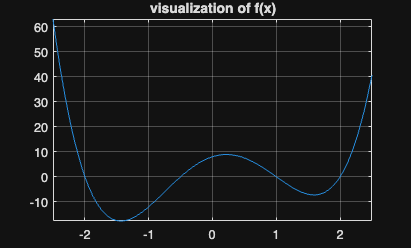


% plotting

fplot(f, [-2.5, 2.5])

grid on

title('visualization of f(x)')

% (b) Plot the function f(x) between the range -2 and 2

% step size of x = 0.5

x_1 = -2:0.5:2

x_1 =    -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000



y_1 = 4*x_1.^4 - 2*x_1.^3 - 18*x_1.^2 + 8*x_1 + 8 

y_1 =          0  -17.5000  -12.0000         0    8.0000    7.5000         0   -7.0000         0


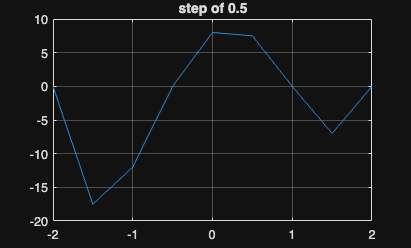


plot(x_1, y_1)

grid on

title('step of 0.5')


% step size of x = 0.1

x_2 = -2:0.1:2

x_2 =    -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000



y_2 = 4*x_2.^4 - 2*x_2.^3 - 18*x_2.^2 + 8*x_2 + 8

y_2 =          0   -6.3336  -11.0656  -14.3856  -16.4736  -17.5000  -17.6256  -17.0016  -15.7696  -14.0616  -12.0000   -9.6976   -7.2576   -4.7736   -2.3296         0    2.1504    4.0664    5.7024    7.0224    8.0000    8.6184    8.8704    8.7584    8.2944    7.5000    6.4064    5.0544    3.4944    1.7864         0   -1.7856   -3.4816   -4.9896   -6.2016   -7.0000   -7.2576   -6.8376   -5.5936   -3.3696         0


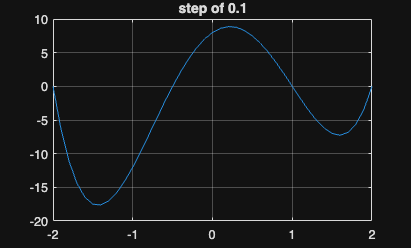


plot(x_2, y_2)

grid on

title('step of 0.1')

% (c) the diff. between the two graphs is that, as the step size decreases,
%     the graph is smoother. 

% 1.2 electric kettle

% (a) practical experiment data

% time as array

time = [0; 5; 10; 15; 20; 30; 40; 50; 60; 70; 80; 90; 100; 110; 120; 130; 140; 150; 160];

% temprature as array

temperature = [22.80; 22.80; 22.80; 22.80; 25.70; 32.10; 36.90; 42.70; ...
               45.80; 51.70; 55.40; 59.10; 64.40; 68.90; 73.10; 77.80; ...
               82.10; 85.90; 92.80];

% Grouping them

experimentTable = table(time, temperature, 'VariableNames', {'Time_s', 'Temperature_C'})

experimentTable = 19×2 table
    Time_s    Temperature_C
    ______    _____________

       0          22.8     
       5          22.8     
      10          22.8     
      15          22.8     
      20          25.7     
      30          32.1     
      40          36.9     
      50          42.7     
      60          45.8     
      70          51.7     
      80          55.4     
      90          59.1     
     100          64.4     
     110          68.9     
     120          73.1     
     130          77.8     


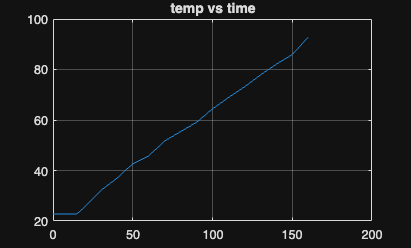


plot(time, temperature)

grid on

title('temp vs time')


% power

Pwr = 2000

Pwr = 2000


% mass

m = 0.5

m = 0.5000


% heat capacity

c = 4.1813

c = 4.1813


% equation

% delta_v = (power * time)/(m * heat capacity)

delta_v = (Pwr * time)/(m * c)

delta_v = 1.0e+05 *

         0
    0.0478
    0.0957
    0.1435
    0.1913
    0.2870
    0.3827
    0.4783
    0.5740
    0.6696
    0.7653
    0.8610
    0.9566
    1.0523
    1.1480


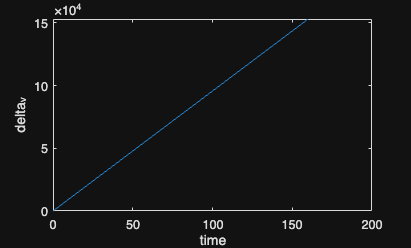


plot(time, delta_v)
xlabel('time')
ylabel('delta_v')

% function in matlab for polynomial curve fitting

% polyfit looks at the messy graph of time vs temp, and find the perfect
% smooth line that passes through it.

p = polyfit(time, temperature, 2)

p =     0.0001    0.4342   19.4125



T_start = temperature(1)

T_start = 22.8000


t = 0

t = 0


T = T_start

T = 22.8000


time_sim = [t]

time_sim = 0


temp_sim = [T]

temp_sim = 22.8000


while T < 90

    t = t+1

    % polyval is always done after polyfit

    % polyval uses the 'p' or points found in the polyfit to find the next
    % point or do a simple predicition.

    T = polyval(p, t)

    time_sim = [time_sim; t];

    temp_sim = [temp_sim; T];

end

t = 1

T = 19.8468

t = 2

T = 20.2814

t = 3

T = 20.7162

t = 4

T = 21.1513

t = 5

T = 21.5866

t = 6

T = 22.0221

t = 7

T = 22.4579

t = 8

T = 22.8939

t = 9

T = 23.3301

t = 10

T = 23.7665

t = 11

T = 24.2032

t = 12

T = 24.6402

t = 13

T = 25.0773

t = 14

T = 25.5147

t = 15

T = 25.9523

t = 16

T = 26.3902

t = 17

T = 26.8283

t = 18

T = 27.2666

t = 19

T = 27.7052

t = 20

T = 28.1440

t = 21

T = 28.5830

t = 22

T = 29.0223

t = 23

T = 29.4618

t = 24

T = 29.9015

t = 25

T = 30.3415

t = 26

T = 30.7817

t = 27

T = 31.2221

t = 28

T = 31.6628

t = 29

T = 32.1037

t = 30

T = 32.5448

t = 31

T = 32.9862

t = 32

T = 33.4278

t = 33

T = 33.8696

t = 34

T = 34.3117

t = 35

T = 34.7540

t = 36

T = 35.1965

t = 37

T = 35.6393

t = 38

T = 36.0823

t = 39

T = 36.5255

t = 40

T = 36.9690

t = 41

T = 37.4127

t = 42

T = 37.8567

t = 43

T = 38.3008

t = 44

T = 38.7452

t = 45

T = 39.1899

t = 46

T = 39.6348

t = 47

T = 40.0799

t = 48

T = 40.5252

t = 49

T = 40.9708

t = 50

T = 41.4166

t = 51

T = 41.8626

t = 52

T = 42.3089

t = 53

T = 42.7554

t = 54

T = 43.2022

t = 55

T = 43.6491

t = 56

T = 44.0964

t = 57

T = 44.5438

t = 58

T = 44.9915

t = 59

T = 45.4394

t = 60

T = 45.8875

t = 61

T = 46.3359

t = 62

T = 46.7845

t = 63

T = 47.2334

t = 64

T = 47.6825

t = 65

T = 48.1318

t = 66

T = 48.5813

t = 67

T = 49.0311

t = 68

T = 49.4811

t = 69

T = 49.9314

t = 70

T = 50.3819

t = 71

T = 50.8326

t = 72

T = 51.2835

t = 73

T = 51.7347

t = 74

T = 52.1861

t = 75

T = 52.6378

t = 76

T = 53.0897

t = 77

T = 53.5418

t = 78

T = 53.9942

t = 79

T = 54.4467

t = 80

T = 54.8996

t = 81

T = 55.3526

t = 82

T = 55.8059

t = 83

T = 56.2594

t = 84

T = 56.7132

t = 85

T = 57.1672

t = 86

T = 57.6214

t = 87

T = 58.0759

t = 88

T = 58.5305

t = 89

T = 58.9855

t = 90

T = 59.4406

t = 91

T = 59.8960

t = 92

T = 60.3517

t = 93

T = 60.8075

t = 94

T = 61.2636

t = 95

T = 61.7199

t = 96

T = 62.1765

t = 97

T = 62.6333

t = 98

T = 63.0903

t = 99

T = 63.5476

t = 100

T = 64.0051

t = 101

T = 64.4628

t = 102

T = 64.9208

t = 103

T = 65.3790

t = 104

T = 65.8374

t = 105

T = 66.2961

t = 106

T = 66.7550

t = 107

T = 67.2141

t = 108

T = 67.6735

t = 109

T = 68.1331

t = 110

T = 68.5929

t = 111

T = 69.0530

t = 112

T = 69.5133

t = 113

T = 69.9738

t = 114

T = 70.4346

t = 115

T = 70.8956

t = 116

T = 71.3568

t = 117

T = 71.8183

t = 118

T = 72.2800

t = 119

T = 72.7419

t = 120

T = 73.2041

t = 121

T = 73.6665

t = 122

T = 74.1292

t = 123

T = 74.5920

t = 124

T = 75.0551

t = 125

T = 75.5185

t = 126

T = 75.9820

t = 127

T = 76.4459

t = 128

T = 76.9099

t = 129

T = 77.3742

t = 130

T = 77.8387

t = 131

T = 78.3034

t = 132

T = 78.7684

t = 133

T = 79.2336

t = 134

T = 79.6991

t = 135

T = 80.1647

t = 136

T = 80.6306

t = 137

T = 81.0968

t = 138

T = 81.5632

t = 139

T = 82.0298

t = 140

T = 82.4966

t = 141

T = 82.9637

t = 142

T = 83.4310

t = 143

T = 83.8986

t = 144

T = 84.3664

t = 145

T = 84.8344

t = 146

T = 85.3026

t = 147

T = 85.7711

t = 148

T = 86.2398

t = 149

T = 86.7088

t = 150

T = 87.1780

t = 151

T = 87.6474

t = 152

T = 88.1170

t = 153

T = 88.5869

t = 154

T = 89.0570

t = 155

T = 89.5274

t = 156

T = 89.9980

t = 157

T = 90.4688

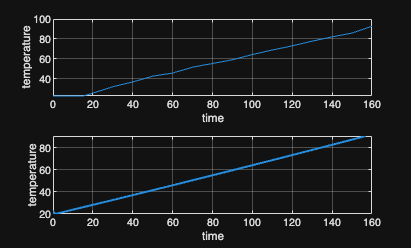


subplot(2, 1, 1)

plot(time, temperature)
grid on
xlabel('time')
ylabel('temperature')

subplot(2, 1, 2)

plot(time_sim, temp_sim, 'LineWidth', 1.5)
grid on
xlabel('time')
ylabel('temperature')


% when using a value of m=1, the time required to boil the water is ~157
% secs. 

% when using a value of m=0.5, the time required to boil the water is ~157
% secs. 

% both are the same. 


% 1.3 Signal reconstruction

% u = 5; x = 0 to 4pi; step pi/4

% y = u * sin(x)

u = 5

u = 5


x = 0:pi/4:4*pi

x =          0    0.7854    1.5708    2.3562    3.1416    3.9270    4.7124    5.4978    6.2832    7.0686    7.8540    8.6394    9.4248   10.2102   10.9956   11.7810   12.5664



y = u * sin(x)

y =          0    3.5355    5.0000    3.5355    0.0000   -3.5355   -5.0000   -3.5355   -0.0000    3.5355    5.0000    3.5355    0.0000   -3.5355   -5.0000   -3.5355   -0.0000



% inaccurate graph is due to big step size (pi/4 = 45) ---> reduce it to
% 0.1

x_accurate = 0:0.1:4*pi

x_accurate =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000



pf_d = polyfit(x,y,7) % the rule

pf_d =    -0.0003    0.0120   -0.2006    1.5784   -5.6700    6.8381    1.5831    0.0498



pv = polyval(pf_d, x_accurate) % the use of the rulw (polyfit)

pv =     0.0498    0.2710    0.5971    0.9994    1.4527    1.9347    2.4262    2.9105    3.3735    3.8034    4.1905    4.5271    4.8072    5.0265    5.1822    5.2728    5.2980    5.2586    5.1563    4.9936    4.7739    4.5010    4.1794    3.8138    3.4093    2.9716    2.5060    2.0182    1.5142    0.9994    0.4796   -0.0397   -0.5532   -1.0558   -1.5425   -2.0089   -2.4507   -2.8639   -3.2450   -3.5907   -3.8983   -4.1654   -4.3901   -4.5707   -4.7061   -4.7956   -4.8389   -4.8360   -4.7874   -4.6940


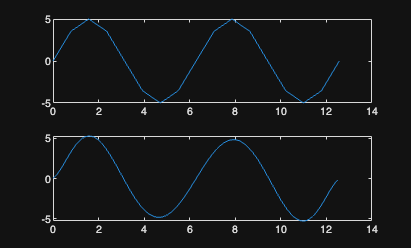


subplot(2,1,1)

plot(x,y)

subplot(2,1,2)

plot(x_accurate, pv)


% from degree of 7, the graph is accurate

% at degree 6, the graph is still not accurate

% grade of polynomial - 7

% 1.4 NTC thermistor char. curve

% non linear relationship b/w resistance and temp.

R0 = 10000

R0 = 10000

T0 = 298.15

T0 = 298.1500

B = 3950

B = 3950


Temp_C = 0:1:100 % temp in kelvin

Temp_C =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


Temp_K = Temp_C + 273.15 % temp convert from C ---> K

Temp_K =   273.1500  274.1500  275.1500  276.1500  277.1500  278.1500  279.1500  280.1500  281.1500  282.1500  283.1500  284.1500  285.1500  286.1500  287.1500  288.1500  289.1500  290.1500  291.1500  292.1500  293.1500  294.1500  295.1500  296.1500  297.1500  298.1500  299.1500  300.1500  301.1500  302.1500  303.1500  304.1500  305.1500  306.1500  307.1500  308.1500  309.1500  310.1500  311.1500  312.1500  313.1500  314.1500  315.1500  316.1500  317.1500  318.1500  319.1500  320.1500  321.1500  322.1500


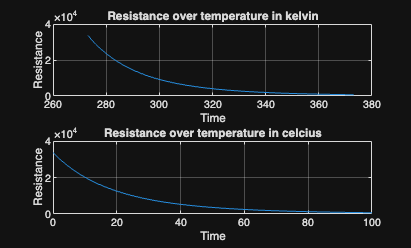


R = R0 .* exp(B .* (1./Temp_K - 1./T0));

subplot(2,1,1)

plot(Temp_K, R)
grid on
title('Resistance over temperature in kelvin')
xlabel('Time')
ylabel('Resistance')

subplot(2,1,2)

plot(Temp_C, R)
grid on
title('Resistance over temperature in celcius')
xlabel('Time')
ylabel('Resistance')



threshold = 2000

threshold = 2000


below_2000 = find(R<2000)

below_2000 =     68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101



alarm_temp = Temp_C(below_2000(1))

alarm_temp = 67